    img_1 = OTrace.imgLaplacian-XTrace.imgLaplacian;
    img_1 = img_1>0;
    img_2 = XTrace.imgLaplacian-OTrace.imgLaplacian;
    img_2 = img_2>0;
    
% xd = conv2(img_1, img, "same");

    
    % Binarization
    A1 = img_1 > 0;
    A2 = img_2 > 0;
    
    % Eliminate small objects
    A1 = bwareaopen(A1, 10, 4);
    A2 = bwareaopen(A2, 10, 4);
    
    % Dilate
    SE = strel('square', 3);
    A1 = imdilate(A1, SE);
    A2 = imdilate(A2, SE);
    
    %
    % Keeping the 2 biggest structures
%     A = bwareafilt(A, 2);
    s1 = regionprops(A1,'centroid');
    centroids1 = cat(1,s1.Centroid);
    s2 = regionprops(A2,'centroid');
    centroids2 = cat(1,s2.Centroid);
%     360 y 300
    

cc1 = bwconncomp(A1); 
stats1 = regionprops(cc1,'Centroid');
centroids1 = cat(1,stats1.Centroid);
idx1 = find([centroids1(:,2)] >= 300 & [centroids1(:,2)] <= 360 ); 
BW21 = ismember(labelmatrix(cc1),idx1);  

cc2 = bwconncomp(A2); 
stats2 = regionprops(cc2,'Centroid');
centroids2 = cat(1,stats2.Centroid);
idx2 = find([centroids2(:,2)] >= 300 & [centroids2(:,2)] <= 360 ); 
BW22 = ismember(labelmatrix(cc2),idx2); 
% centroids(:,2)
% figure, imagesc(A)
% figure, imagesc(BW2)

facilIon = BW21+BW22;
facilIon = facilIon > 0;
img = facilIon;


% z_1 = BW2;
% 
% z_2 = BW2;

zzz_1 = z_1-z_2;
zzz_1 = zzz_1>0;
zzz_2 = z_2-z_1;
zzz_2 = zzz_2>0;

rsp = BW2 .* OTrace.imgSub;




imagesc(flip(zzz_1))

zzz_2 = bwmorph(zzz_2,'thin', Inf);
% zzz_1 = bwskel(zzz_1, 'MinBranchLength', 6);
[row,col] = find(flip(zzz_2)~=0);

% imshow(A)
% hold on
% plot(centroids(:,1),centroids(:,2),'b*')
% hold off





freq = IonogramData.FreqData./(10^3);
plot(freq,"LineWidth",2)
xlabel("píxeles","FontSize",14); ylabel("Frecuencia (MHz)","FontSize",14)
xlim([0, length(freq)])
ylim([min(freq), max(freq)])

plot(IonogramData.RangeData)
xlabel("píxeles","FontSize",14); ylabel("Altura virtual (km)","FontSize",14)

print -depsc Ionograma_O_IntensityProfile_ProyY.eps



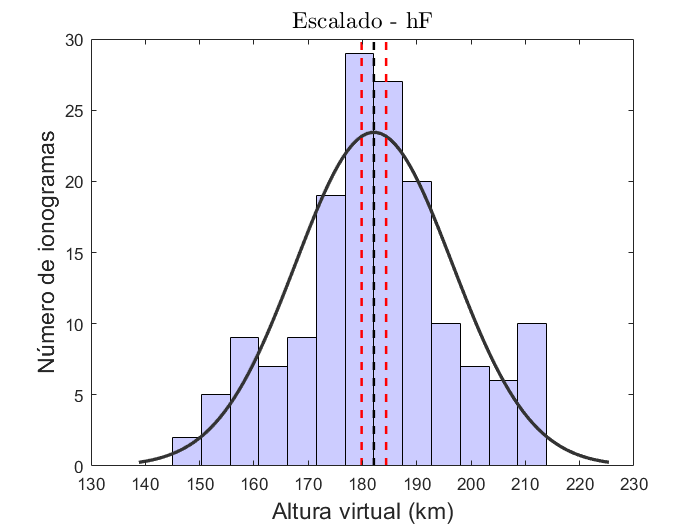

A = table2array(ScalhF);
% A = ScalhF.("hF - 0*delta");
h = histfit(A(:));
h(1).FaceColor = [.8 .8 1];
h(2).Color = [.2 .2 .2];
xlabel("Altura virtual (km)","FontSize",14); ylabel("Número de ionogramas","FontSize",14)
title("Escalado - hF",'Interpreter','latex', "FontSize",14)

z1 = (175-180)/std(A(:));
z2 = (185-180)/std(A(:));

SEM = std(A(:))/sqrt(length(A(:)));               % Standard Error
% ts = tinv([1-0.6368  0.6368],length(A(:))-1);      % T-Score
ts = tinv([0.0250  0.9750],length(A(:))-1);      % T-Score
CI = mean(A(:)) + ts*SEM;                      % Confidence Intervals

hold on
plot([1 1]*CI(1), ylim, '--r',"LineWidth",1.5)                % First Vertical Line at 7x=4.50
plot([1 1]*mean(A(:)), ylim, '--k',"LineWidth",1.5)               % First Vertical Line at 8x=13.50
plot([1 1]*CI(2), ylim, '--r',"LineWidth",1.5)               % First Vertical Line at 8x=13.50
hold off


% hold on
% plot([1 1]*175, ylim, '--r',"LineWidth",2)                % First Vertical Line at 7x=4.50
% plot([1 1]*180, ylim, '--k',"LineWidth",2)               % First Vertical Line at 8x=13.50
% plot([1 1]*185, ylim, '--r',"LineWidth",2)               % First Vertical Line at 8x=13.50
% hold off


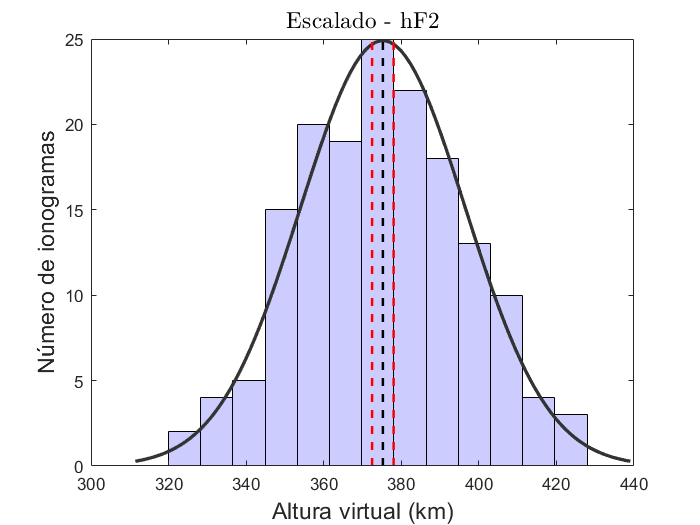

A = table2array(ScalhF2);
% A = cat(1,ScalhF.("hF - 5*delta"),ScalhF.("hF + 5*delta"));
h = histfit(A(:));
h(1).FaceColor = [.8 .8 1];
h(2).Color = [.2 .2 .2];
xlabel("Altura virtual (km)","FontSize",14); ylabel("Número de ionogramas","FontSize",14)
title("Escalado - hF2",'Interpreter','latex', "FontSize",14)

SEM = std(A(:))/sqrt(length(A(:)));               % Standard Error
% ts = tinv([1-0.6368  0.6368],length(A(:))-1);      % T-Score
ts = tinv([1-0.95  0.95],length(A(:))-1);      % T-Score
CI = mean(A(:)) + ts*SEM;                      % Confidence Intervals

hold on
plot([1 1]*CI(1), ylim, '--r',"LineWidth",1.5)                % First Vertical Line at 7x=4.50
plot([1 1]*mean(A(:)), ylim, '--k',"LineWidth",1.5)               % First Vertical Line at 8x=13.50
plot([1 1]*CI(2), ylim, '--r',"LineWidth",1.5)               % First Vertical Line at 8x=13.50
hold off

A = table2array(Scalfof1);
h = histfit(A(:));
h(1).FaceColor = [.8 .8 1];
h(2).Color = [.2 .2 .2];
xlabel("Frecuencia (MHz)","FontSize",14); ylabel("Número de ionogramas","FontSize",14)
title("Escalado - hF",'Interpreter','latex', "FontSize",14)


SEM = std(A(:))/sqrt(length(A(:)));               % Standard Error
ts = tinv([1-0.95  0.95],length(A(:))-1);      % T-Score
CI = mean(A(:)) + ts*SEM;                      % Confidence Intervals

hold on
plot([1 1]*CI(1), ylim, '--r',"LineWidth",1.5)                % First Vertical Line at 7x=4.50
plot([1 1]*mean(A(:)), ylim, '--k',"LineWidth",1.5)               % First Vertical Line at 8x=13.50
plot([1 1]*CI(2), ylim, '--r',"LineWidth",1.5)               % First Vertical Line at 8x=13.50
hold off


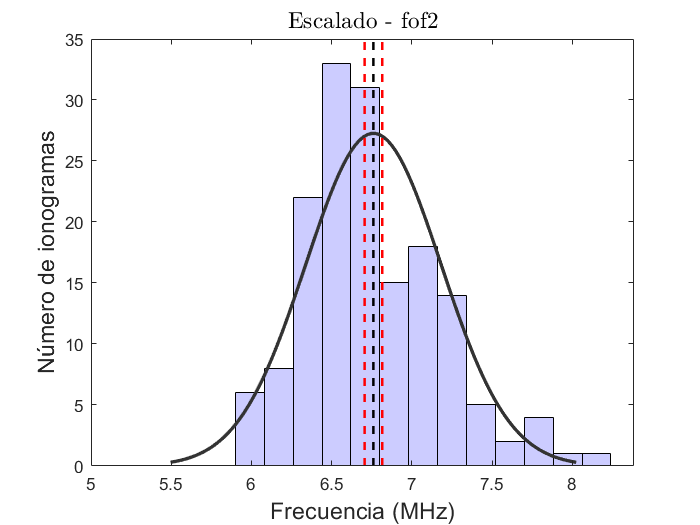

A = table2array(Scalfof2);
h = histfit(A(:));
h(1).FaceColor = [.8 .8 1];
h(2).Color = [.2 .2 .2];
xlabel("Frecuencia (MHz)","FontSize",14); ylabel("Número de ionogramas","FontSize",14)
title("Escalado - fof2",'Interpreter','latex', "FontSize",14)


SEM = std(A(:))/sqrt(length(A(:)));               % Standard Error
ts = tinv([1-0.95  0.95],length(A(:))-1);      % T-Score
ts = [-1.960 1.960]
CI = mean(A(:)) + ts*SEM;                      % Confidence Intervals

hold on
plot([1 1]*CI(1), ylim, '--r',"LineWidth",1.5)                % First Vertical Line at 7x=4.50
plot([1 1]*mean(A(:)), ylim, '--k',"LineWidth",1.5)               % First Vertical Line at 8x=13.50
plot([1 1]*CI(2), ylim, '--r',"LineWidth",1.5)               % First Vertical Line at 8x=13.50
hold off